%audio info

info = audiodevinfo

info = struct with fields:
     input: [1×5 struct]
    output: [1×4 struct]


nDevices = audiodevinfo(1)

nDevices = 5

% name = audiodevinfo(1,-1)
DriverVersion = audiodevinfo(1,0,"DriverVersion")

DriverVersion = 'Core Audio'

support = audiodevinfo(1,2,44100,16,1)

support = logical
   0


%devID = audiodevinfo(1,"devName")
suppDevID = audiodevinfo(1,44100,16,1)

suppDevID = 0

%record audio and plot


Fs = 44100; 
nBits = 8; 
nChannels = 1; 
ID = -1;       % default audio input device 
recObj = audiorecorder(Fs,nBits,nChannels,ID);

disp("Begin speaking.") 

Begin speaking.



recDuration = 3; % record for 3 seconds
recordblocking(recObj,recDuration);
disp("End of recording.")

End of recording.


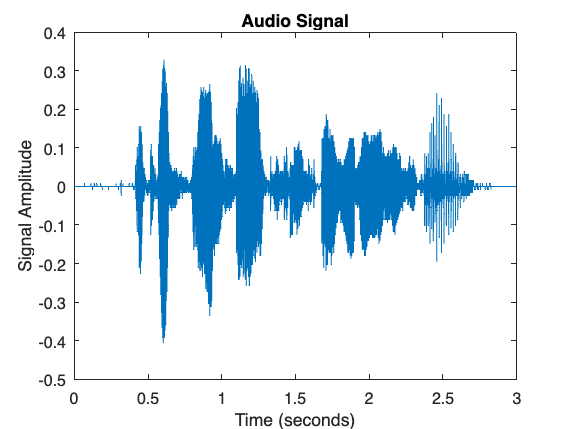


%play(recObj);

% disp(myRecording)
y = getaudiodata(recObj);
% xlim([0 5]);
plot(0:1/Fs:recDuration-1/Fs, y);
title('Audio Signal');
xlabel('Time (seconds)');

ylabel('Signal Amplitude');

%create  .wav file

filename = './ece2312.wav';
% y_new = [zeros(25,1);y(1:end-25)] %%%for one of the last parts
audiowrite(filename,y,Fs);
% sound(y,Fs);

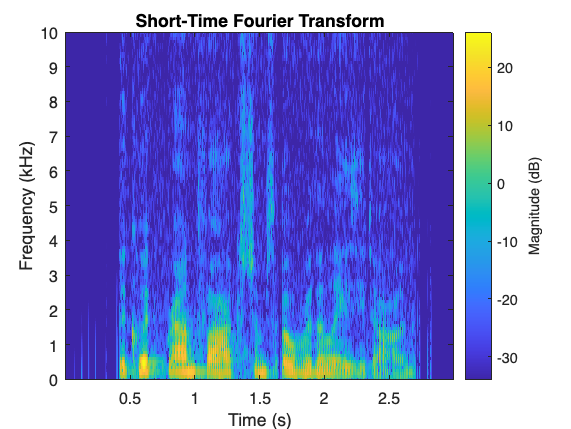


%plot .wav file

stft(y,Fs,Window = kaiser(256,5),OverlapLength=220, FFTLength =512);
ylim([0 10]) %can play around with limits to highlight speech section

% distance / speed of sound
% ans * Fs
% final ans should be 10-30 samples
%

% size (y)
% size ([y,y])
% change y to [y,y_new] for one oif the last parts


% 10^(dB/10) for attenuatin 